# Checking the Weather Using MATLAB and Python 

There are benefits and challenges in bringing multiple programming languages together using Application Programming Interfaces (APIs). In this script, you have an existing Python module that contains functions for accessing the OpenWeather API and doing some initial cleaning of the data. To practice using existing code rather than rewriting the functionality into MATLAB, this script walks through using the existing `checkweather.py` code in the Run Python Code Live Task. The exploration and analysis of the data will happen in MATLAB. This toy example should demonstrate the possibilities for using code provided by others in the framework of code you write yourself. This can provide benefits for collaboration and time savings even when it may well be possible to [rewrite the code](https://www.mathworks.com/help/matlab/ref/webread.html) to use [fewer tools](https://www.mathworks.com/help/matlab/ref/jsondecode.html). 

**Getting started: **Follow the instructions in [Using Python with MATLAB](matlab: edit UsingPythonWithMATLAB.mlx) to ensure that your system is configured to run compatible versions of MATLAB, Python, and the Run Python Code Live Task. 

## Use Python to pull current information from the OpenWeather API

### Create an OpenWeather account 

- Navigate to [https://home.openweathermap.org/users/sign_up](https://home.openweathermap.org/users/sign_up) to create your account. 

- Once you have an account, visit [https://home.openweathermap.org/home](https://home.openweathermap.org/home) and select **API keys** from the menu

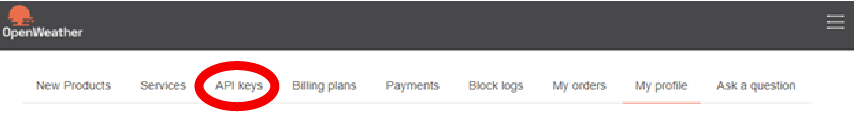

          3. Save your API key in `HelperFunctions` as `myAPIkey.txt`. Then run the code below to create a variable named `apikey` that contains your API key as a string.

if exist("myAPIkey.txt","file")
apikey = readlines("myAPIkey.txt");
disp("The API key is: " + apikey)
else
    disp("You need to save an Openweather API key in myAPIkey.txt to use this script.")
end

myPath = pwd;
if contains(myPath,"/MATLAB Drive/")
    localSetPythonEnvMO
end

          4. Choose a location by latitude and longitude, create a label for your location, and make a choice of the unit system. The [units available](https://openweathermap.org/api/one-call-3#how) from the OpenWeather API are "standard", "metric", or "imperial".

lat = 42.2834;   % Natick, US
lon = -71.3495;  % Natick, US
location = "Natick, US";
unitChoice = "imperial";
% lat = 4.6097;    % Bogota, Columbia
% lon = -74.0817;  % Bogota, Columbia
% location = "Bogota, Columbia"
% lat = 12.9762;   % Bengaluru, India
% lon = 77.6033;   % Bengaluru, India
% location = "Bengaluru, Inda";
% unitChoice = "metric";

        5. Insert a Run Python Code Live Task here and configure it to run the Python statements 

Note that this requires four input variables: `lat`, `lon`, `apikey`, and `unitChoice`. It also returns two output variables: `currentWeather` and `forecastWeather`. 

% Open the Live Task Run Python Code here


## Exploring the results of your API call

### Checking Data Types

The return variables are both Python dictionaries. 

class(forecastWeather)

This means they are collections of key/value pairs:

currentWeather

You can check the list of keys:

keys(currentWeather)

or even access values:

currentWeather{"feels_like"}

### Converting Data Types

To fully interface between languages, you should convert the Python dictionary into a MATLAB data type. 

  **Try. **Use the `struct` command to create a MATLAB structure from the returned variable `currentWeather`. Name the new variable `curWeather`. Do not suppress the output. 

curWeather = struct(currentWeather)

 **Reflect**. 

- What happened to the keys and values from the Python dictionary?

There are still both MATLAB and Python data types inside `curWeather`. This happens because there is a conservative list of Python data types that can be automatically converted to equivalent MATLAB data types. 

** Exercise 1.**

- Identify two fields that contain MATLAB doubles.

- Identify two fields that contain Python integers.

- Identify two fields that contain Python strings.

- Identify one field that contains a Python list.

**Solution:**

### Choosing Data Type Conversions

As the programmer, you have additional information about what type of data is contained in each field. Use this information to choose appropriate MATLAB data types. 

Convert the `py.str` values to MATLAB strings using `string` and the `py.int` values to numeric MATLAB variables using `double. `

curWeather.dt = double(curWeather.dt);
curWeather.sunrise = double(curWeather.sunrise);
curWeather.sunset = double(curWeather.sunset);
curWeather.timezone = string(curWeather.timezone);

Because we don't know what is inside of the list in `curWeather.weather`, let's do a bit of exploring:

curWeather.weather

Which options make the most sense for a Python dictionary containing integers, strings, and alphanumeric codes? There is only one element, a dictionary, in this Python list, so that we can pull it out into a structure:

weatherDescr = curWeather.weather{1};
weather = struct(weatherDescr)

Okay, we can decide which of these values we are interested in. Do you want to explore the [`id` codes](https://openweathermap.org/weather-conditions#Weather-Condition-Codes-2)? Or do you want to see the verbal description of the weather? Do you want to use the [icons](https://openweathermap.org/weather-conditions#How-to-get-icon-URL) from OpenWeatherMap?

Let's start by just looking at the verbal descriptions:

weather.main = string(weather.main);
weather.description = string(weather.description)

Now we've got a verbal description of the weather for the day!

** Exercise 2.**

Read the [API documentation](https://openweathermap.org/api/one-call-api) to discover how the time is stored, and then read the documentation for [`datetime`](matlab: doc datetime) to find the correct `dateType` to use with `"ConvertFrom"`. You will also need to use the optional `"TimeZone"` argument.

**Solution:**

## Presenting the Weather Forecast

Knowing the current weather is nice, but that is also usually easy to figure out. It is more important to have an idea of what the future weather is likely to be, especially in parts of the world where the conditions can change rapidly:

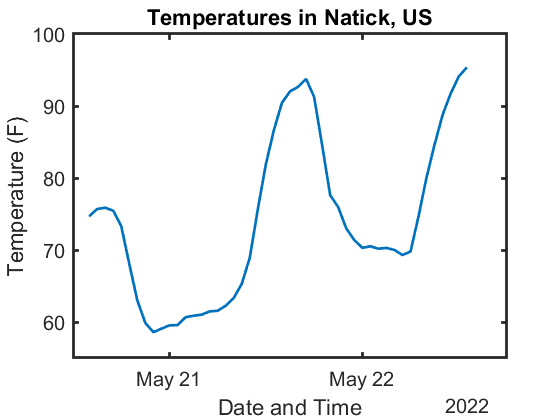

** Exercise 3. **Repeat the datatype conversions for `forecastWeather`, so that you have a structure array of MATLAB data types. Call the resulting structure `predictedWeather` and keep the fields the same. 

#### Plot the predicted temperature as a function of time

Use the information in `unitChoice` to determine the correct units to apply.


% Plot the predicted temperature against time
plot(predictedWeather.Times,predictedWeather.temp)

% Set up the labels on the plot correctly, including units
if unitChoice == "imperial"
    tempLabel = "(F)";
    windLabel = "(mph)";
elseif unitChoice == "metric"
    tempLabel = "(C)"
    windLabel = "(m/s)";
elseif unitChoice == "standard"
    tempLabel = "(K)";
    windLabel = "(m/s)";
end
title("Temperatures in "+ location)
xlabel("Date and Time")
ylabel("Temperature " +tempLabel)

#### Plot the predicted barometric pressure as a function of time

% Set up a symbolic unit 
u = symunit;
% create a symbolic pressure variable with units
predPressure = predictedWeather.pressure*u.hPa;
% Choose a unit you want to use for displaying the results
pUnit = "mmHg";

switch pUnit
    case "mmHg"
        predPressure = rewrite(predPressure,u.mmHg);
    case "atm"
        predPressure = rewrite(predPressure,u.atm);
    case "bar"
        predPressure = rewrite(predPressure,u.bar);
end

% Convert from symbolic representations to doubles and strings
[pressure,pUnits] = separateUnits(predPressure);
pressure = double(pressure);
pLabel = symunit2str(pUnits(1));

plot(predictedWeather.Times,pressure)
title("Predicted Atmospheric Pressure in " + location)
xlabel("Date and Time")
ylabel("Pressure (" + pLabel + ")")

** Exercise 4. **

Plot the predicted temperature and the predicted pressure on the same axes. Combine the previous two plots, of temperature and pressure using [`yyaxis`](https://www.mathworks.com/help/matlab/ref/yyaxis.html) to track both scales. Label the x-axis, both y-axes, and include an appropriate title and legend. 

#### Plot the wind speed and direction

Create a plot of the wind speed, as a magnitude, and direction, as an angle, on a polar plot. 

clf
windDir = predictedWeather.deg/180*pi;   % The wind angle in radians
thetaInterp = interp1(1:48,windDir,1:1/12:48,"pchip");
rInterp = interp1(1:48,predictedWeather.speed,1:1/12:48,"spline");

** Exercise 5. **Considering the results of different data sets, or working purely analytically, explain why the code below is necessary to properly interpolate the wind direction. 

deltas = diff(windDir);
idx = find((abs(deltas)>pi) == 1);
for k = 1:length(idx)
    if deltas(idx(k)) < 0 && windDir(idx(k))> pi
        thetaInterp(1+(idx(k)-1)*12:1+idx(k)*12) = interp1([1 2],[windDir(idx(k)) windDir(idx(k)+1)+2*pi],1:1/12:2,"linear");
    elseif deltas(idx(k)) > 0 && predictedWeather.deg(idx(k)) < 180
        thetaInterp(1+(idx(k)-1)*12:1+idx(k)*12) = interp1([1 2],[windDir(idx(k))+2*pi windDir(idx(k)+1)],1:1/12:2,"linear");
    end
end

Generate the polar plot of the wind speed and direction as functions of time.

polarplot(thetaInterp,rInterp)
subtitle(windLabel)
ax = gca;
ax.RLim = [0 max(rInterp)];

  **Try**. What happens if you do not set the `ThetaZeroLocation`? Or do not set the `ThetaTickLabel` values?

ax.ThetaZeroLocation = "top";
ax.ThetaDir = "clockwise";
ax.ThetaTickLabel{1} = "N";
ax.ThetaTickLabel{4} = "E";
ax.ThetaTickLabel{7} = "S";
ax.ThetaTickLabel{10} = "W";

Animate the plot of wind speed and direction so you can observe the variability over time. Do you expect a steady wind or a variable one?

hold on
p = polarplot(thetaInterp(1),rInterp(1),"-*","SeriesIndex",2);
hold off
for k = 1:length(thetaInterp)
    p.ThetaData = [0 thetaInterp(k)];
    p.RData = [0 rInterp(k)];
    if mod(k,2)==0
        drawnow
    end
    % The interpolation was at 1/12 of an hour, or 5 minute intervals
    predTime = predictedWeather.Times(1)+(k-1)*minutes(5);
    title("Wind Prediction: " + string(predTime))
end

##  Creating a Simple Interactive Live Weather Display

- In the Live Editor tab on the toolstrip, select **Save As** from the **Save** dropdown in the **File** section. Use it to save a copy of this script as `MyWeatherApp.mlx`.

- Decide how you want your users to interact with your app. Do you want them to select one of several pre-programmed locations using a dropdown menu, or do you want to give them the option to set the latitude, longitude, and name for any location using edit fields? Once you have decided, use the **Insert Control** option in the MATLAB Toolstrip  to add either the dropdown or edit field live controls with your preferred values as defaults. 

- Select the breadcrumbs in the top right corner of the Run Python Code Live Task and select "Convert Task to Editable Code". This will allow you to hide the API calls from your users by selecting the Hide Code view in Step 5.

- Choose which plots you want to present in your app. Do they also have options (e.g., choosing the units for barometric pressure)? How do you want to group your code? How do you want to run each section of code? Buttons or checkboxes can work well for controlling these decisions. 

- Simplify the view by hiding the code. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

- Delete unnecessary text, and change the introductory text appropriately.

- Ensure that the instructions for interacting with the live controls are clear. You may need to right-click to access the **Configure Control** menu option, where you can set the label text, default values, and other options. 

- Enjoy your weather display!

## Further Explorations

If this has whet your appetite, it is possible to go much farther with integrating code back and forth between [MATLAB and Python](https://www.mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html). 

- Documentation on [calling Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html)

- Documentation on [calling MATLAB from Python](https://www.mathworks.com/help/matlab/matlab-engine-for-python.html)

function localSetPythonEnvMO
if pyenv().Status == "Loaded"
    if pyenv().Version == "2.7"
        disp("You have Python 2.7 loaded, but this module requires Python 3.8+.")
        disp("Please restart MATLAB Online by typing quit() at the command line,")
        disp("and then open MATLABwithPython.prj")
    else
        p = pyenv();
    end
elseif ~exist("p","var")
    p = pyenv("Version","/usr/bin/python3");   % for MATLAB Online
end
end